# Replicating Strategy. Question 1d

No. It doesn't converge like the first. This is the due to the absence of the annual return. Without the return, there wouldn't be cumulation.

Given values

S0 = 72.99;         % Closing price
mu = 11.75/100;     % Annualized return
sigma = 24.98/100;  % Annualized Volatility
rho = 1/100;        % Annualized interest rate
K = 80;             % Strike price
T = 42;             % Period - 2 months (21 days per month)

## Creating the new plot

N = 50;

delta_array = zeros([1, N]);
for n=1:N
    delta_array(n) = Q1c(mu, sigma, rho, S0, K, T, n);
end

delta_array

delta_array = 	1.0e+-14 *

         0    0.0034    0.0045    0.0162    0.0185    0.0206    0.0224    0.0322    0.0688         0    0.0575         0    0.0210         0         0         0    0.0242    0.0249    0.1537    0.1447    0.0270         0    0.0141    0.0289    0.1773    0.2412    0.0154    0.0470    0.0159         0    0.0165    0.0671         0         0    0.0527    0.0356         0         0    0.0371    0.0376    0.0190    0.0386    0.0195    0.0197         0    0.0202         0         0    0.0209    0.0211


Compute the call option

d1 = (log(S0/K) + rho*T)/(sigma*sqrt(T)) + 1/2*sigma*sqrt(T);
c = S0 * normpdf(d1) - K * exp(-rho*T) * normpdf(d1 - sigma*sqrt(T) )

c = 7.1054e-15

c_upper = 0.98 * c;
c_lower = 1.02 * c;

The plot

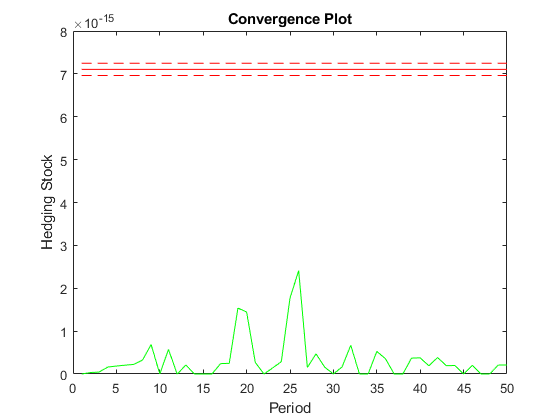

figure(1)
plot(1:N, delta_array, '-g', [1, N], [c, c], '-r', [1, N], [c_lower, c_lower], '--r', [1, N], [c_upper, c_upper], '--r')
title('Convergence Plot')
xlabel('Period')
ylabel('Hedging Stock')